%%%%  Norm of difference 
%%%%%%%%%%%%%%
%%% tau=0.05
nu=[0 0.02 0.04 0.06 0.08 0.1]

nu =          0    0.0200    0.0400    0.0600    0.0800    0.1000


%%%%% dif in max norm
difmax =[0 1.5436 3.2826 4.8952 6.4261 7.8929];
normfit=polyfit(nu,difmax,1)

normfit =    79.6066    0.0264


difmaxcor=polyval(normfit,nu)

difmaxcor =     0.0264    1.6185    3.2107    4.8028    6.3949    7.9871


%%% sum of squared error
Q=(difmax-difmaxcor)*(difmax-difmaxcor)'

Q = 0.0299

%%%%% tau=0.025
difmax2=[0 1.5416 3.2741 4.8790 6.4024 7.8624]

difmax2 =          0    1.5416    3.2741    4.8790    6.4024    7.8624


normfit2=polyfit(nu,difmax2,1)

normfit2 =    79.2847    0.0290


difmaxcor2=polyval(normfit2,nu)

difmaxcor2 =     0.0290    1.6147    3.2004    4.7861    6.3718    7.9575


%%% sum of squared error
Q2=(difmax2-difmaxcor2)*(difmax2-difmaxcor2)'

Q2 = 0.0302

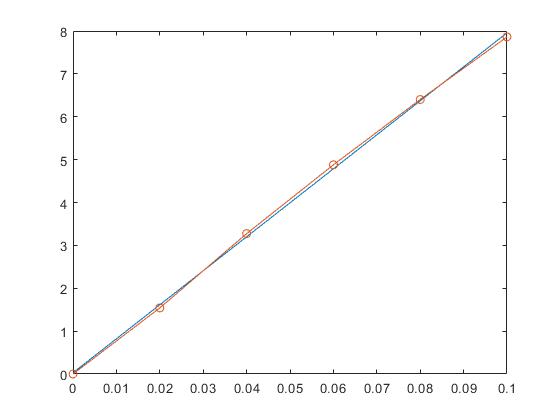

%%%%%%% plot graphic
nulist=linspace(0,0.1);
normlist=polyval(normfit2,nulist);
plot(nulist,normlist,nu,difmax2,'-o')

%%%%% tau=0.0125
nu=[0 0.02 0.04 0.06 0.08 0.1]

nu =          0    0.0200    0.0400    0.0600    0.0800    0.1000


difmax4=[0 1.6420 3.5069 5.2400 6.8865 8.4653]

difmax4 =          0    1.6420    3.5069    5.2400    6.8865    8.4653


normfit4=polyfit(nu,difmax4,1)

normfit4 =    85.4187    0.0192


difmaxcor4=polyval(normfit4,nu)

difmaxcor4 =     0.0192    1.7276    3.4359    5.1443    6.8527    8.5611


%%% sum of squared error
Q2=(difmax4-difmaxcor4)*(difmax4-difmaxcor4)'

Q2 = 0.0322

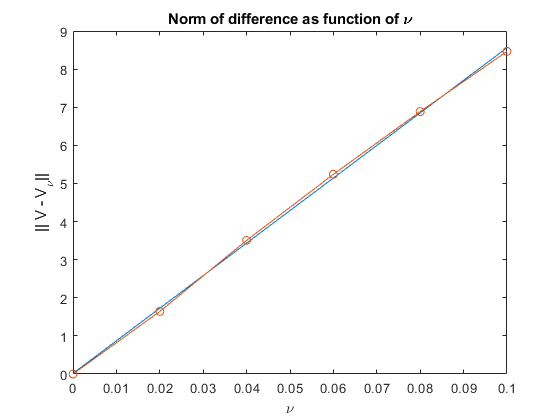

%%%%%%% plot graphic
nulist=linspace(0,0.1);
normlist=polyval(normfit4,nulist);
plot(nulist,normlist,nu,difmax4,'-o')
xlabel('\nu')
ylabel('|| V - V_{\nu}||')
title(['Norm of difference as function of \nu'])

%%%%%%  Convergence
max1=max(abs(difmax4-difmax2))

max1 = 0.0154

max2=max(abs(difmax-difmax2))

max2 = 0.0305

max1/max2

ans = 0.5049